% Using edfread
[data, header] = edfread('chb01_01.edf');



disp(data.Properties.VariableNames);

    {'SignalLabel1_FP1_F7'}    {'SignalLabel2_F7_T7'}    {'SignalLabel3_T7_P7'}    {'SignalLabel4_P7_O1'}    {'SignalLabel5_FP1_F3'}    {'SignalLabel6_F3_C3'}    {'SignalLabel7_C3_P3'}    {'SignalLabel8_P3_O1'}    {'SignalLabel9_FP2_F4'}    {'SignalLabel10_F4_C4'}    {'SignalLabel11_C4_P4'}    {'SignalLabel12_P4_O2'}    {'SignalLabel13_FP2_F8'}    {'SignalLabel14_F8_T8'}    {'SignalLabel15_T8_P8'}    {'SignalLabel16_P8_O2'}    {'SignalLabel17_FZ_CZ'}    {'SignalLabel18_CZ_PZ'}    {'SignalLabel19_P7_T7'}    {'SignalLabel20_T7_FT9'}    {'SignalLabel21_FT9_FT10'}    {'SignalLabel22_FT10_T8'}    {'SignalLabel23_T8_P8'}



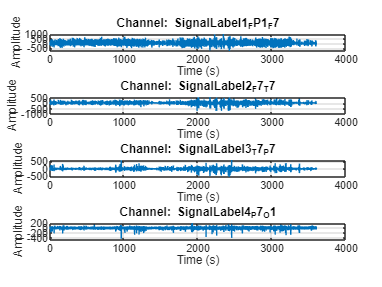

% Assuming you have already loaded the EEG data in the `dataTable` variable
% and the time vector is known (sample rate = 256 Hz)

fs = 256; % Sampling frequency (256 Hz)
chunk_duration = 3600; % Duration of each chunk (6 seconds)
samples_per_chunk = fs * chunk_duration; % Number of samples in each 6-second chunk

% Define the time vector for the first 6 seconds
time_vector = (0:samples_per_chunk-1) / fs; % Time vector for 6 seconds

% Channel names (as given)
channels = data.Properties.VariableNames(1:4);

% Number of channels
num_channels = length(channels);

% Create a figure for plotting
figure;

% Loop through each channel and plot the first 6 seconds of data
for j = 1:num_channels
    % Extract the data for the current channel (adjust this according to your variable structure)
    signal_data = cell2mat(data.(channels{j})); % First 6 seconds of the channel
    
    % Plot the data in a subplot
    subplot(num_channels, 1, j); % Create subplots for each channel
    plot(time_vector, signal_data);
    title(['Channel: ' channels{j}]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end


% Adjust subplot layout


% Assuming dataTable is already loaded with the EEG data and you have the correct signal labels

% Define the channels


% Initialize an empty matrix to store the concatenated data
% The size of the matrix will be (num_time_points * num_channels)
all_data = [];

% Loop through each time point (0 to 5 seconds in this case, adjust if needed)
for t = 1:chunk_duration  % Loop for each second (0 sec to 5 sec)
    % Initialize an empty matrix for the current time point
    current_time_data = [];
    
    % Loop through each channel and concatenate the data
    for c = 1:num_channels
        % Get the signal data for the current channel at the current time point
        signal_data = data{t, channels{c}};  % Adding 1 to t because MATLAB indices start at 1
        
        % Concatenate the data for the current channel at the current time point
        current_time_data = [current_time_data signal_data];
    end
    
    % Append the current time point data to the all_data matrix
    all_data = [all_data; current_time_data];
end



connected_data =  cell2mat(all_data);


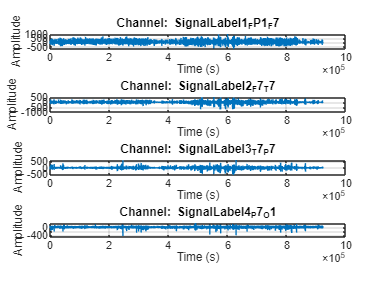

% Assuming you have already loaded the EEG data in the `dataTable` variable
% and the time vector is known (sample rate = 256 Hz)

fs = 256; % Sampling frequency (256 Hz)
chunk_duration =30; % Duration of each chunk (6 seconds)
samples_per_chunk = fs * chunk_duration; % Number of samples in each 6-second chunk

% Define the time vector for the first 6 seconds
time_vector = (0:samples_per_chunk-1) / fs; % Time vector for 6 seconds

% Channel names (as given)
channels = data.Properties.VariableNames(1:4);

% Number of channels
num_channels = length(channels);

% Create a figure for plotting
figure;

% Loop through each channel and plot the first 6 seconds of data
for j = 1:num_channels
    % Extract the data for the current channel (adjust this according to your variable structure)
    signal_data = connected_data(:,j); % First 6 seconds of the channel
    
    % Plot the data in a subplot
    subplot(num_channels, 1, j); % Create subplots for each channel
    plot(signal_data);
    title(['Channel: ' channels{j}]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

% Adjust subplot layout

% Normalize Data
connected_data = normalize(connected_data,"range",[0,10]);

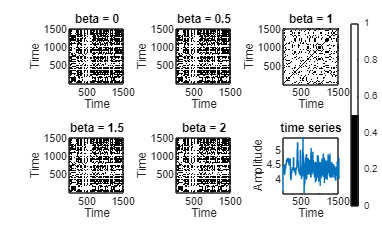

plot_betas(connected_data(1:256*6,1),3,10,'threshold', true, 'epsilon', 0.05);